clear;

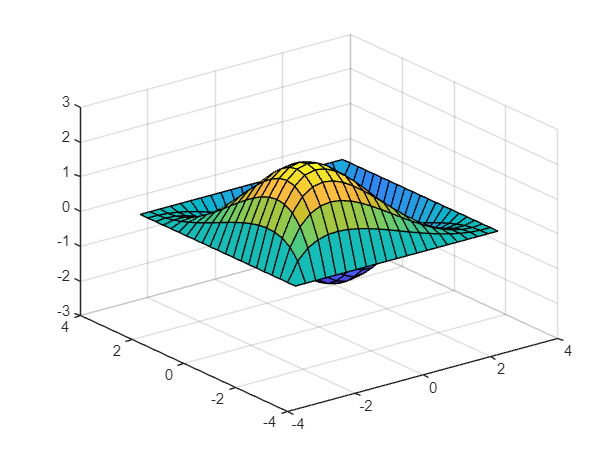

% ddu/dyy + ddu/dxx = x^2 + y^2-
% [0,1] x [0,1]
f = @(x,y) x + y;

% parameters
N = 20;
L = 3;
h = 2*L/N;

x = -L:h:L;
y = -L:h:L;
[X,Y] = meshgrid(x,y);
w = zeros(N+1,N+1);

% for i = 1:N+1
%     w(i,1) = 0;
%     w(i,N+1) = 0;
% end
% 
% for j = 1:N+1
%     w(1,j) = 0;
%     w(N+1,j) = 0;
% end

n = N-1;
I = eye(n);
c = [-2 1 zeros(1,n-2)];
D = toeplitz(c);
D = kron(D,I) + kron(I,D);
% spy(D)

% F = h^2*f(Y(1:n,1:n),X(1:n,1:n));
F = h^2*f(Y(2:N,2:N),X(2:N,2:N));
F = F(:);

U = D \ F;
U = reshape(U,n,n);
w(2:N,2:N) = U;
surf(X,Y,w)

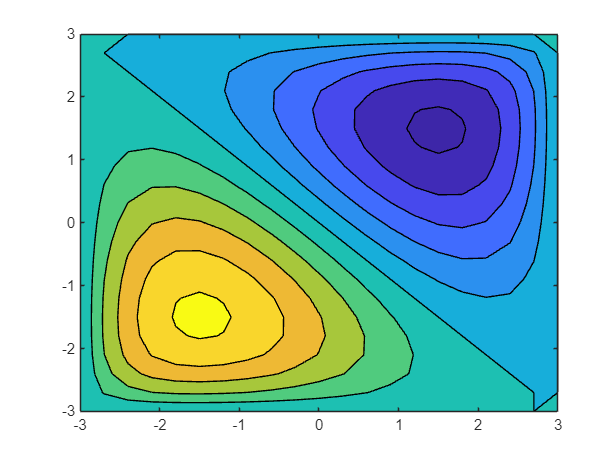

contourf(X,Y,w)

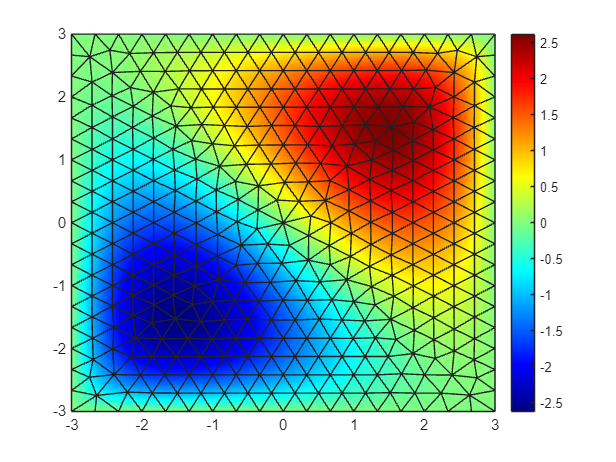

model = createpde();
R1 = [3, 4, -3, 3, 3, -3, -3, -3, 3, 3]';
g = decsg(R1);
geometryFromEdges(model,g);
applyBoundaryCondition(model, "dirichlet", Edge = [1,2,3,4], u = 0);
specifyCoefficients(model, m=0, d=0, c=1, a=0, f=@fcoeffunction);
generateMesh(model);

results = solvepde(model);
u = results.NodalSolution;
msh = results.Mesh;
pdeplot(msh, XYData=u, ...
    ColorMap = "jet", Mesh = "on");

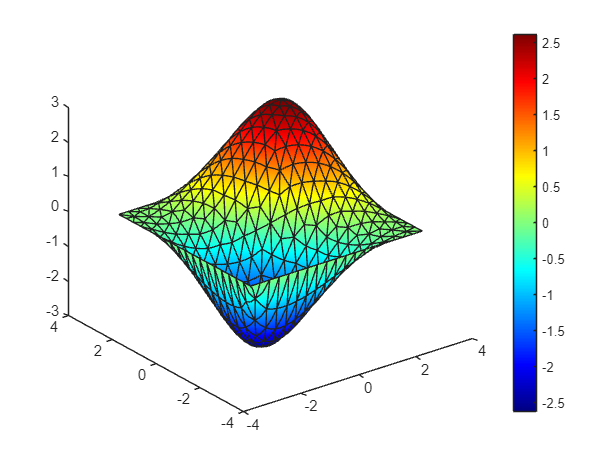

pdeplot(msh, XYData=u, ZData=u, ...
    ColorMap = "jet", Mesh = "on");

function f = fcoeffunction(location,state)
    N = 1; % Number of equations
    nr = length(location.x); % Number of columns
    f = zeros(N,nr); % Allocate f

    % Now the particular functional form of f
    f(1,:) = location.x + location.y;
end